clear all
x=6;
y=9;
x1k=[x];
x2k=[y];
M=1:1:200;
for i=2:length(M)
    fun = @(w)(1-w)^2+5*(y-w^2)^2;
    w1 = fminbnd(fun,0.01,100);
    x=w1;
    x1k(i)=x;
    fun = @(w)(1-x)^2+5*(w-x^2)^2;
    w2 = fminbnd(fun,0.01,100);
    y=w2;
    x2k(i)=y;
end


x1 = linspace(-10,10,500);
x2 = linspace(-10,10,500);
[X1,Y1] = meshgrid(x1,x2);
Z =(1-X1).^2 + 5*(Y1-X1.^2).^2 ;

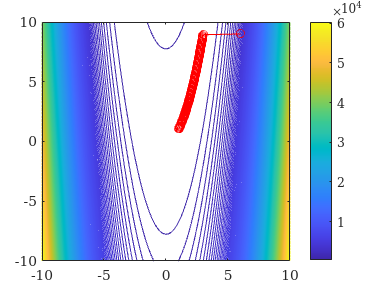

figure
title("Contorno para f(x)")
contour(X1,Y1,Z,200);
hold on
colorbar
xlim([-10,10]);
ylim([-10,10]);
plot (x1k,x2k,"r - o")
hold off